sum(1./(1:100))

ans = 5.1874

prod(1:100)  %乘积

ans = 9.3326e+157

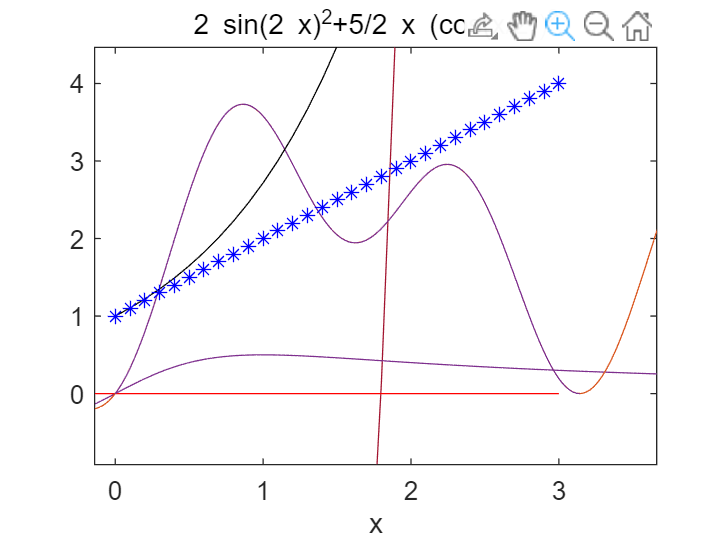

% p255 例5 不等式
x = 0:0.1:3;
f1=exp(x);
f2=1+x;
plot(x,f1,'k-',x,f2,'b*')

xlim([-0.01 3.14])
ylim([-0.40 4.05])

syms x;
f = exp(x)-x-1

$$f = {\mathrm{e}}^{x}-x-1$$

df=diff(f,x);
c=fzero('exp(x)-x-1', 0)

c = 0

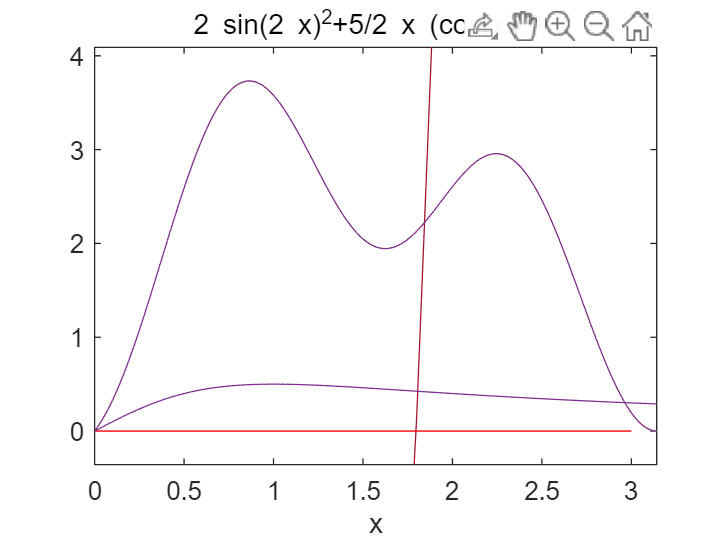

% 极小值与极大值
f = '2*sin(2*x)^2+5/2*x*(cos(x/2))^2';
ezplot(f, [0, pi])

[xmin,ymin] = fminbnd(f, 0, pi)

xmin = 1.6239

ymin = 1.9446

f = '-2*sin(2*x)^2+5/2*x*(cos(x/2))^2';
[xmax,ymax] = fminbnd(f, 0, pi)

xmax = 2.4629

ymax = -1.2280

ymax = -ymax

ymax = 1.2280

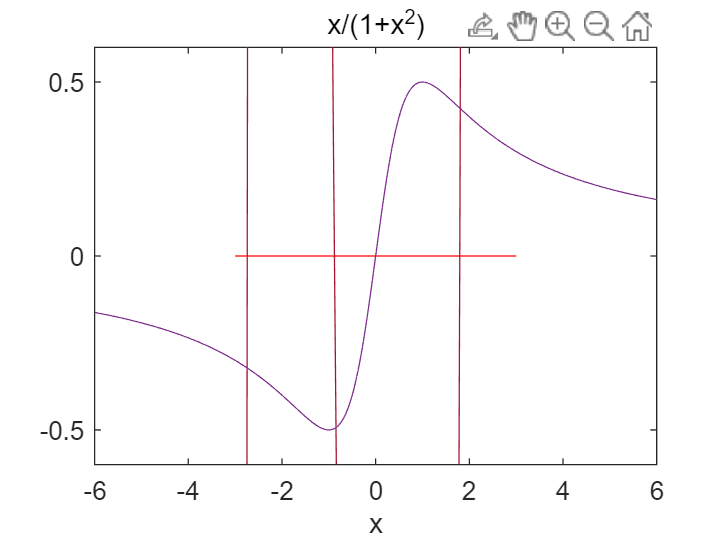

ezplot('x/(1+x^2)', [-6, 6])

syms x
f='x/(1+x^2)';
[xmin,ymin] = fminbnd(f,-10,10)

xmin = -1.0000

ymin = -0.5000

f='-x/(1+x^2)';
[xmax,ymax]=fminbnd(f,-10,10)

xmax = 1.0000

ymax = -0.5000

ymax = -ymax  %最大值要取负

ymax = 0.5000

syms x;
f = x^5+x^4-4*x^3+2*x^2-3*x-7;
r1 = roots([1 1 -4 2 3 -7])

r1 =   -2.5353 + 0.0000i
  -1.2756 + 0.0000i
   0.6859 + 1.0166i
   0.6859 - 1.0166i
   1.4391 + 0.0000i


r2 = fzero(char(f), -5)

r2 = -2.7446

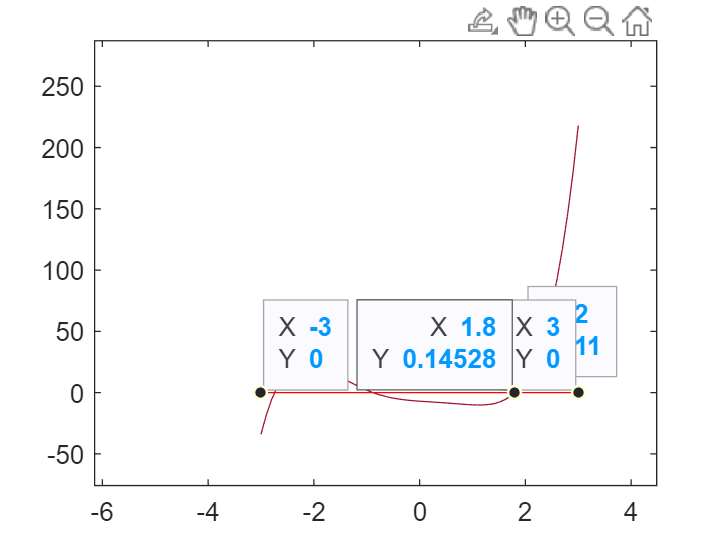

x = -3:0.1:3;
y = x.^5+x.^4-4*x.^3+2*x.^2-3*x-7;
plot(x, y); hold on;
plot([-3, 3], [0, 0], 'r')

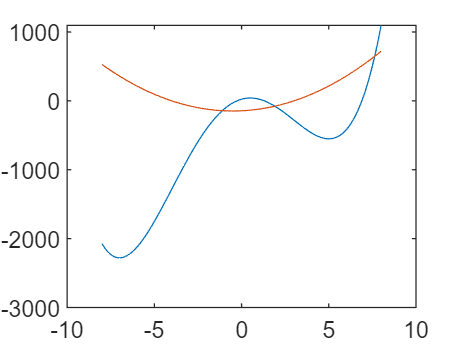

syms x
g = x^4+2*x^3-72*x^2+70*x+24;
dg = diff(g);
d2g = diff(dg);
r = solve(d2g, x);
d2v = [];
gv = [];

for v = -8:0.1:8
    x = v;
    y1 = eval(g);
    y2 = eval(d2g);
    gv = [gv y1];
    d2v = [d2v y2];
end

v = -8:0.1:8;
plot(v, gv, v, d2v);

syms x
diff(x^3-2*x+1)

$$ans = 3\,x^{2}-2$$

ans = 3*x^2-2

$$ans = 3\,x^{2}-2$$

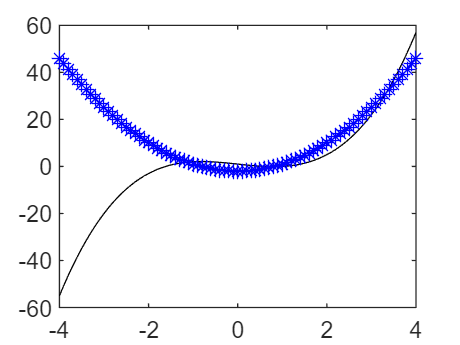

x = -4:0.1:4;
y1 = x.^3-2*x+1;
y2 = 3*x.^2-2;
plot(x, y1, 'k-', x, y2, 'b*')

c = roots([3,0,-2])

c =     0.8165
   -0.8165


x = -1;
daoshuju=eval('3*x^2-2')

daoshuju = 1

x = 0;
daoshuju=eval('3*x^2-2')

daoshuju = -2

x = 1;
daoshuju=eval('3*x^2-2')

daoshuju = 1

利用定义求导数：

syms x dx
f=((x+dx)^a-x^a)/dx;  
diff(f,dx,0)

$$ans = 1$$

syms t
x=exp(t)*cos(t)

$$x = {\mathrm{e}}^{t}\,\cos\left(t\right)$$

y=exp(t)*sin(t)

$$y = {\mathrm{e}}^{t}\,\sin\left(t\right)$$

df=diff(y,t)/diff(x,t)

$$df = \frac{{\mathrm{e}}^{t}\,\cos\left(t\right)+{\mathrm{e}}^{t}\,\sin\left(t\right)}{{\mathrm{e}}^{t}\,\cos\left(t\right)-{\mathrm{e}}^{t}\,\sin\left(t\right)}$$

syms x
f=x^n

$$f = x^{n}$$

df=diff(f,2)

$$df = n\,x^{n-2}\,\left(n-1\right)$$

g=sin(x)

$$g = \sin\left(x\right)$$

dg=diff(g,5)

$$dg = \cos\left(x\right)$$

x=0.12*pi;
eval(dg)

ans = 0.9298

syms x
diff('x^3-3*x^2+x+1')

ans =    -26   -43    -6     6    -9    78   -26   -44    -7    77   -77     6


x=1:0.1:3

x =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000


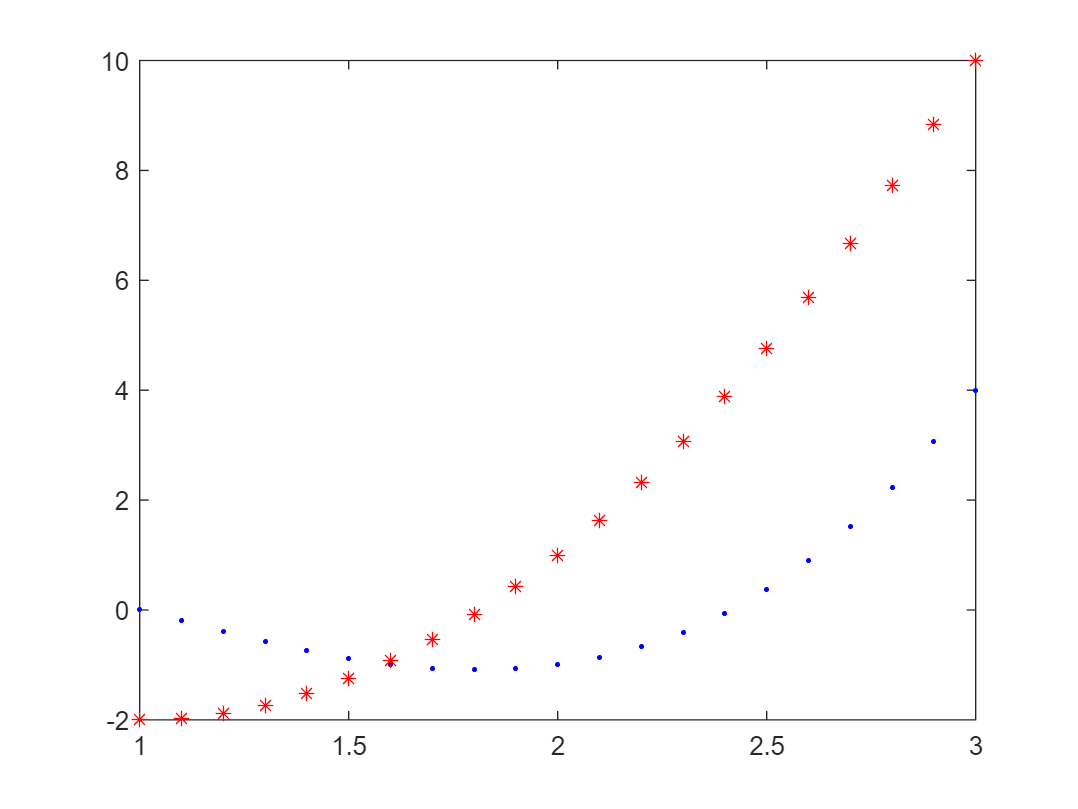

y1=x.^3-3*x.^2+x+1;
y2=3*x.^2-6*x+1;
plot(x,y1,'b.',x,y2,'r*')

syms x
limit((sin(x)/x)^(1/(1-cos(x))), x, 0)
limit((exp(x)-exp(-x)-2*x)/(x-sin(x)),x,0)

syms x
a = limit((x+1/x+3)/x,x,inf)
b = limit((x+1/x+3)-a*x,x,inf)
x = -3:0.1:3
f = x+1./x+3
y = a*x+b
plot(x,f,'b',x,y,'r')
grid on

ezplot('1/(1-x*x)', [-3,3])
grid on

syms x
limit(1/(1-x*x), x, -1, 'right')
limit(1/(1-x*x), x, 1, 'right')

ezplot('(1+2*x)/(1-x)', [-3,4])
ezplot('x^3-x', [-10, 10])
syms x
limit((1+2*x)/(1-x), x, 1,'right')
limit(x^3-x, x, inf)

syms x
ezplot('(1+1/x)^x', [-100, 100])
limit((1+1/x)^x, x, 0)
grid on

ezplot('sin(x)/x', [-10*pi, 10*pi])
grid on
syms x
limit(sin(x)/x, x, 0)

ezplot('atan(x)', [-50, 50])
syms n
limit(atan(n), n, inf)

syms n
limit((2*n^3+1)/(5*n^3+1),n,inf)

x = rand(5, 8)
sum(x)
prod(x)